syms x v y

int((y^2)*y, 0, 1)

$$ans = \frac{1}{4}$$

int((2*y-y^2)*y, 1, 2)

$$ans = \frac{11}{12}$$

v = y-x

$$v = y-x$$

fx = piecewise((x>=0)&(x<=1), 2*x, 0)

$$fx = \left\{ \begin{array}{cl} 2\,x & \text{ if }x\in \left[0,1\right]\\ 0 & \mathrm{otherwise} \end{array}\right.$$

fv = piecewise((v>=0)&(v<=1), 1, 0)

$$fv = \left\{ \begin{array}{cl} 1 & \text{ if }y-x\in \left[0,1\right]\\ 0 & \mathrm{otherwise} \end{array}\right.$$


fxy = fx*fv

$$fxy = \left\{ \begin{array}{cl} 2\,x & \text{ if }y-x\in \left[0,1\right]\wedge x\in \left[0,1\right]\\ 0 & \mathrm{otherwise} \end{array}\right.$$

fy = simplify(int(fxy, [-inf,inf]))

$$fy = \left\{ \begin{array}{cl} y^{2} & \text{ if }y\in \left(0,1\right]\\ 1-{\left(y-1\right)}^{2} & \text{ if }y\in \left[1,2\right)\\ 0 & \text{ if }y\notin \mathbb{R}\vee y\leq 0\vee 2\leq y \end{array}\right.$$


mu_y = int(y*fy, [-inf,inf])

$$mu\_y = \frac{7}{6}$$

Ey2 = int(y^2*fy, [-inf,inf])

$$Ey2 = \frac{3}{2}$$

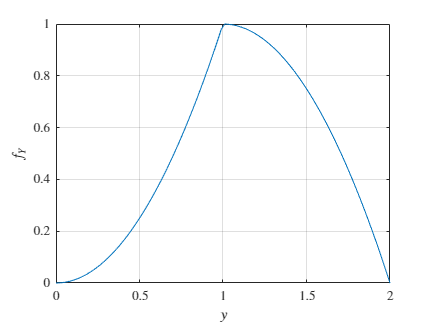

t = linspace(0,2);
f_y = eval(subs(fy,t));
figure
plot(t,f_y)
xlabel('$y$')
ylabel('$f_Y$')
grid on

fx_y = fxy/fy

$$fx\_y = \left\{ \begin{array}{cl} \frac{2\,x}{y^{2}} & \text{ if }0\leq y-x\wedge x\in \left[0,1\right]\wedge y\in \left(0,1\right]\\ -\frac{2\,x}{{\left(y-1\right)}^{2}-1} & \text{ if }y-x\leq 1\wedge x\in \left[0,1\right]\wedge y\in \left[1,2\right)\\ 0 & \text{ if }y\in \left(0,2\right) \end{array}\right.$$

gy = int(x*fx_y, x, [-inf,inf]) 

$$gy = \left\{ \begin{array}{cl} \frac{2\,y}{3} & \text{ if }y\in \left(0,1\right]\\ \frac{2\,y}{3}+\frac{2}{3\,y}-\frac{2}{3} & \text{ if }y\in \left(1,2\right)\\ 0 & \text{ if }y\notin \left(0,2\right) \end{array}\right.$$

clear
syms x v y
y = x+v

$$y = v+x$$

p = [1; y; y^2; y^3];

fx = 2*x;
fv = 1;

Rxp = int(fv * int(fx*x*p', x, [0,1]), [0,1])

$$Rxp = \left(\begin{array}{cccc} \frac{2}{3} & \frac{5}{6} & \frac{101}{90} & \frac{8}{5} \end{array}\right)$$

Rp = int(fv * int(fx*p*p', x, [0,1]), [0,1])

$$Rp = \left(\begin{array}{cccc} 1 & \frac{7}{6} & \frac{3}{2} & \frac{31}{15}\\ \frac{7}{6} & \frac{3}{2} & \frac{31}{15} & 3\\ \frac{3}{2} & \frac{31}{15} & 3 & \frac{127}{28}\\ \frac{31}{15} & 3 & \frac{127}{28} & \frac{85}{12} \end{array}\right)$$

Rx = int(fx*x*x',x, [0,1])

$$Rx = \frac{1}{2}$$


M = Rxp*inv(Rp)

$$M = \left(\begin{array}{cccc} -\frac{127}{597} & \frac{922}{597} & -\frac{560}{597} & \frac{140}{597} \end{array}\right)$$

M = eval(M)

M =    -0.2127    1.5444   -0.9380    0.2345


p = M*p

$$p = \frac{922\,v}{597}+\frac{922\,x}{597}-\frac{560\,{\left(v+x\right)}^{2}}{597}+\frac{140\,{\left(v+x\right)}^{3}}{597}-\frac{127}{597}$$

error = Rx - M*Rxp'

$$error = \frac{347}{10746}$$

error = eval(error)

error = 0.0323

y = linspace(0,2,100)

y =          0    0.0202    0.0404    0.0606    0.0808    0.1010    0.1212    0.1414    0.1616    0.1818    0.2020    0.2222    0.2424    0.2626    0.2828    0.3030    0.3232    0.3434    0.3636    0.3838    0.4040    0.4242    0.4444    0.4646    0.4848    0.5051    0.5253    0.5455    0.5657    0.5859    0.6061    0.6263    0.6465    0.6667    0.6869    0.7071    0.7273    0.7475    0.7677    0.7879    0.8081    0.8283    0.8485    0.8687    0.8889    0.9091    0.9293    0.9495    0.9697    0.9899



px = polyval(fliplr(M), y)

px =    -0.2127   -0.1819   -0.1518   -0.1225   -0.0939   -0.0661   -0.0389   -0.0124    0.0134    0.0385    0.0629    0.0867    0.1099    0.1324    0.1543    0.1757    0.1964    0.2165    0.2361    0.2551    0.2736    0.2915    0.3090    0.3259    0.3423    0.3582    0.3737    0.3886    0.4032    0.4173    0.4309    0.4442    0.4570    0.4694    0.4815    0.4932    0.5045    0.5155    0.5262    0.5365    0.5465    0.5562    0.5656    0.5747    0.5836    0.5922    0.6006    0.6087    0.6167    0.6244


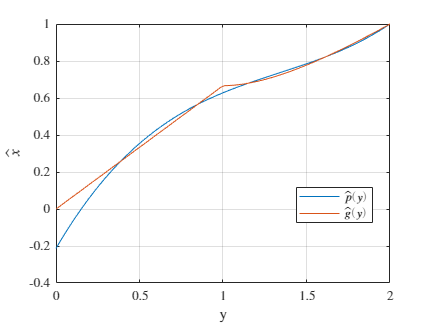


n = 100;
Exy = zeros(1,n);
for i = 1:n
    if y(i) <= 1
        Exy(i) = y(i)*2/3;
    elseif y(i) <= 2 && y(i) > 1
        Exy(i) = 2/3*(y(i)+1/y(i)-1);
    end
end

figure
plot(y,px)
hold on;
plot(y,Exy)
grid on
legend('$\hat{p}(y)$','$\hat{g}(y)$', 'Location','best')
xlabel('y')
ylabel('$\hat{x}$')

x = rand(1,10000);

n = x<0.01;
sum(n)

ans = 103

clear
syms x y
mu_x = int(4*pi^(-1)*sqrt(1-x^2)*x, [0,1])

$$mu\_x = \frac{1911387046407553}{4503599627370496}$$

eval(mu_x)

ans = 0.4244

var_x = int(4/pi*sqrt(1-x^2)*x^2, [0,1]) - mu_x^2

$$var\_x = \frac{5734161139222659\,\pi }{72057594037927936}-\frac{3653400441174589165682975447809}{20282409603651670423947251286016}$$

eval(var_x)

ans = 0.0699

eval(int(4/pi*sqrt(1-x^2), [0,1]))

ans = 1

Ex2 = int(4/pi*x^2*sqrt(1-x^2), [0,1])

$$Ex2 = \frac{5734161139222659\,\pi }{72057594037927936}$$

eval(Ex2)

ans = 0.2500

Egy2 = int((1/2*sqrt(1-y^2))^2*4/pi*sqrt(1-y^2), [0,1])

$$Egy2 = \frac{3}{16}$$

eval(int(2/pi*(1-y^2), [0,1]))

ans = 0.4244

clear
syms x y
p = [1; y; y^2; y^3];

fxy = 4/pi

fxy = 1.2732


Rxp = eval(int(int(fxy*x*p', x, [0,sqrt(1-y^2)]), [0,1]))

Rxp =     0.4244    0.1592    0.0849    0.0531


Rp = eval(int(int(fxy*p*p', x, [0,sqrt(1-y^2)]), [0,1]))

Rp =     1.0000    0.4244    0.2500    0.1698
    0.4244    0.2500    0.1698    0.1250
    0.2500    0.1698    0.1250    0.0970
    0.1698    0.1250    0.0970    0.0781


Ex2 = int(4/pi*x^2*sqrt(1-x^2), [0,1])

$$Ex2 = \frac{5734161139222659\,\pi }{72057594037927936}$$

Rx = eval(Ex2)

Rx = 0.2500


M = Rxp*inv(Rp)

M =     0.5067   -0.1197    0.1953   -0.4730


p = M*p

$$p = -\frac{4160719297845\,y^{3}}{8796093022208}+\frac{1718231421363\,y^{2}}{8796093022208}-\frac{4210279735867\,y}{35184372088832}+\frac{285228170887909}{562949953421312}$$

error = Rx - M*Rxp'

error = 0.0625

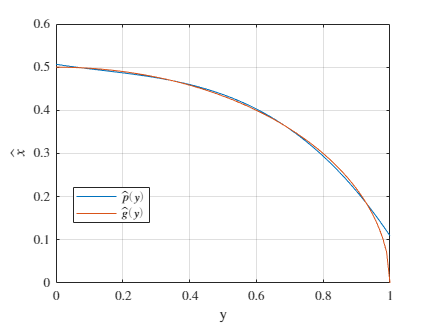

y = linspace(0,1,100);

px = polyval(fliplr(M), y);

Exy = 1/2*sqrt(1-y.^2);

figure
plot(y,px)
hold on;
plot(y,Exy)
grid on
legend('$\hat{p}(y)$','$\hat{g}(y)$', 'Location','best')
xlabel('y')
ylabel('$\hat{x}$')